## Step Size Titration 

Try to find a step size decay scheme that works that matches the CMA-ES.

mu_init = 50; 
mu_fin = 7.33; 
n_gen = 50;
mu_list = linspace(mu_init, mu_fin, n_gen);
sin_mu_list = sin(mu_list / 180 * pi);

mu_list_log = logspace(log10(mu_init), log10(mu_fin), n_gen);
sin_mu_list_log = sin(mu_list_log / 180 * pi);

mu_list_inv = 1./linspace(1/mu_init, 1/mu_fin, n_gen);
sin_mu_list_inv = sin(mu_list_inv / 180 * pi);

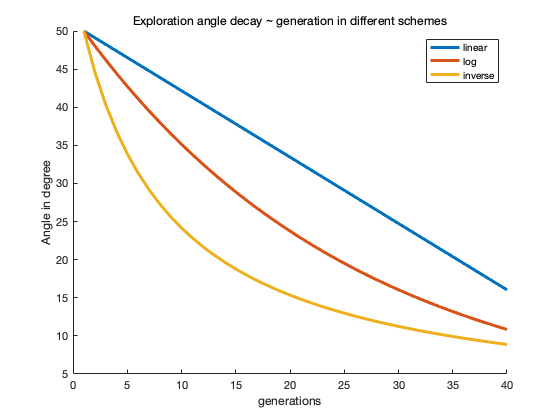

figure;clf;hold on 
plot(1:40, mu_list(1:40),"LineWidth",3)
plot(1:40, mu_list_log(1:40),"LineWidth",3)
plot(1:40, mu_list_inv(1:40),"LineWidth",3)
legend(["linear", "log", "inverse"])
ylabel("Angle in degree")
xlabel("generations")
title("Exploration angle decay ~ generation in different schemes")

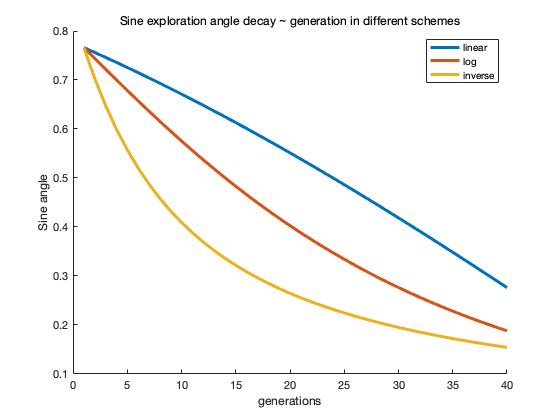

figure;clf;hold on 
plot(1:40, sin_mu_list(1:40),"LineWidth",3)
plot(1:40, sin_mu_list_log(1:40),"LineWidth",3)
plot(1:40, sin_mu_list_inv(1:40),"LineWidth",3)
ylabel("Sine angle")
xlabel("generations")
legend(["linear", "log", "inverse"])
title("Sine exploration angle decay ~ generation in different schemes")

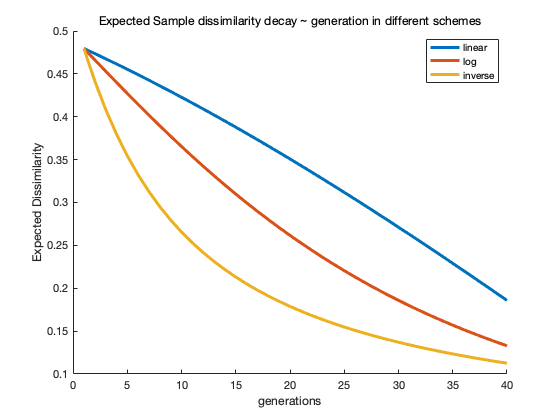

figure;clf;hold on 
plot(1:40, 0.02 + 0.6 * sin_mu_list(1:40),"LineWidth",3)
plot(1:40, 0.02 + 0.6 * sin_mu_list_log(1:40),"LineWidth",3)
plot(1:40, 0.02 + 0.6 * sin_mu_list_inv(1:40),"LineWidth",3)
ylabel("Expected Dissimilarity")
xlabel("generations")
legend(["linear", "log", "inverse"])
title("Expected Sample dissimilarity decay ~ generation in different schemes")